# Module 1: Load and initialize

# Load

## Load reaction network

### Network defined in .m files

#### Schlogl 1-D lattice

clear all
lattice_edge = 6; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_6"


%rate constants
kdif = 0.15;    %diffusion
r01 = 6;    
r10 = 11;
r23 = 6;
r32 = 1;

Schlogl_1D_lattice
plotnam = string(lattice_edge)+"-Schlogl"

plotnam = "6-Schlogl"

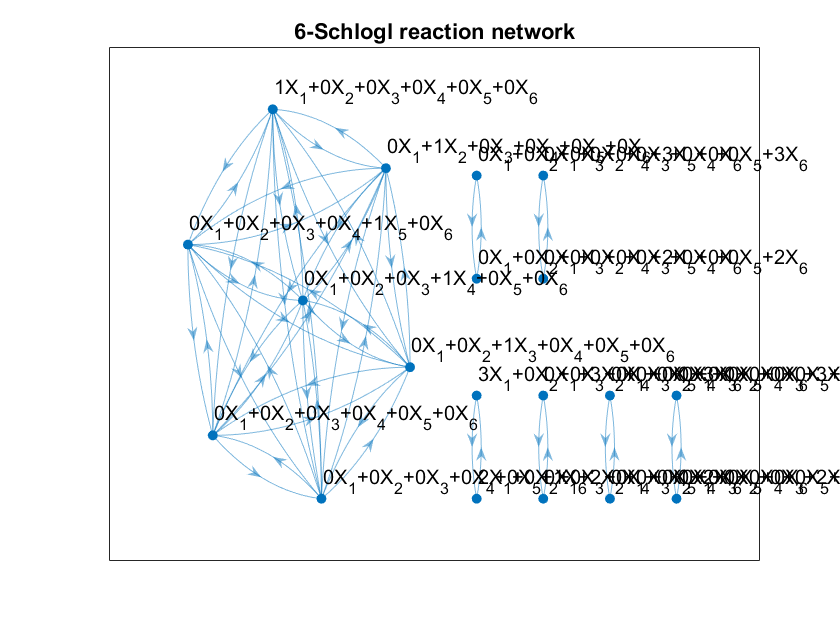

Hypergraph_plotter

a = 1

a = 1

#### Selkov

clear all
model_name = "Selkov"

model_name = "Selkov"

Selkov_model
plotnam = "Selkov"

plotnam = "Selkov"

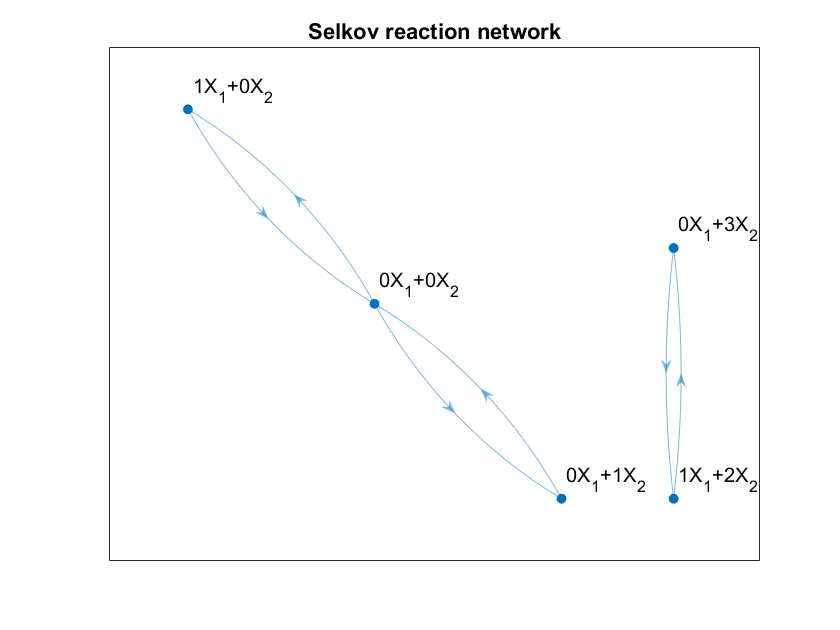

Hypergraph_plotter

### Networks from Feinberg CRN software output formatted files

- Syntrophy network

- Cluster model networks

#### Syntrophy

clear all

$$Ham = \left(0.0023\,{\mathrm{e}}^{p_{1}-p_{2}}-0.0023\right)\,{q_{2}}^{3}+q_{1}\,\left(0.0023\,{\mathrm{e}}^{p_{2}-p_{1}}-0.0023\right)\,{q_{2}}^{2}+\left(1.3333\,{\mathrm{e}}^{-p_{2}}-1.3333\right)\,q_{2}+54.0408\,{\mathrm{e}}^{p_{1}}+1.9592\,{\mathrm{e}}^{p_{2}}+q_{1}\,\left(0.6667\,{\mathrm{e}}^{-p_{1}}-0.6667\right)-56$$

$$Eqns = \left(\begin{array}{c} \left(\frac{0.0023\,z_{1}}{z_{2}}-0.0023\right)\,{q_{2}}^{3}+q_{1}\,\left(\frac{0.0023\,z_{2}}{z_{1}}-0.0023\right)\,{q_{2}}^{2}+\left(\frac{1.3333}{z_{2}}-1.3333\right)\,q_{2}+54.0408\,z_{1}+1.9592\,z_{2}+q_{1}\,\left(\frac{0.6667}{z_{1}}-0.6667\right)-56=0\\ -\frac{z_{2}\,\left(\frac{1.3333\,q_{2}}{{z_{2}}^{2}}-\frac{0.0023\,q_{1}\,{q_{2}}^{2}}{z_{1}}+\frac{0.0023\,{q_{2}}^{3}\,z_{1}}{{z_{2}}^{2}}-1.9592\right)}{z_{1}\,\left(\frac{0.0023\,{q_{2}}^{3}}{z_{2}}-\frac{0.6667\,q_{1}}{{z_{1}}^{2}}-\frac{0.0023\,q_{1}\,{q_{2}}^{2}\,z_{2}}{{z_{1}}^{2}}+54.0408\right)}=\frac{{\mathrm{dq}}_{2}}{{\mathrm{dq}}_{1}} \end{array}\right)$$

  
model_name = "SYN3_FINAL"
filnam = '..\Data\'+ model_name;
Extract_rxn_net_feinberg_1

#### Cluster w/Catalysis

clear all
model_name = "Cluster_3_catalyst"

ans = 10

ans = 5

filnam = '..\Data\'+ model_name;

ans = 0

plotnam = "3-D Cluster model with catalysis"
Extract_rxn_net_feinberg_1

#### Cluster w/catalyst+template

clear all

filnam = "..\Data\Bertini\Schlogl_1_6_bert.txt"

model_name = "Cluster_3_catalyst_w_temp"
filnam = '..\Data\'+ model_name;
plotnam = "3-D Cluster model with catalysis & templating"
Extract_rxn_net_feinberg_1

filnam_sol = "..\Data\Schlogl_1_6_bert_roots.txt"

Notice, the X_i label is arbirary. Whereas, in the cluster index C_i, the index i is a cluster lattice index. The vector v_i = i is a conserved vector for a realistic cluster Hamiltonian denoting a closed system.

## Hamiltonian and derivatives

Save _Ham.mat in 'data' folder

pos_root_arr =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.6838    1.6838    2.0000    2.0000    2.3162    2.3162
    1.6838    1.6838    2.0000    2.3162    2.0000    2.3162
    1.6838    1.6838    2.0000    2.3162    2.3162    2.0000
    1.6838    1.6838    2.3162    2.0000    2.0000    2.3162
    1.6838    1.6838    2.3162    2.0000    2.3162    2.0000
    1.6838    1.6838    2.3162    2.3162    2.0000    2.0000
    1.6838    2.0000    1.6838    2.0000    2.3162    2.3162
    1.6838    2.0000    1.6838    2.3162    2.0000    2.3162
    1.6838    2.0000    1.6838    2.3162    2.3162    2.0000


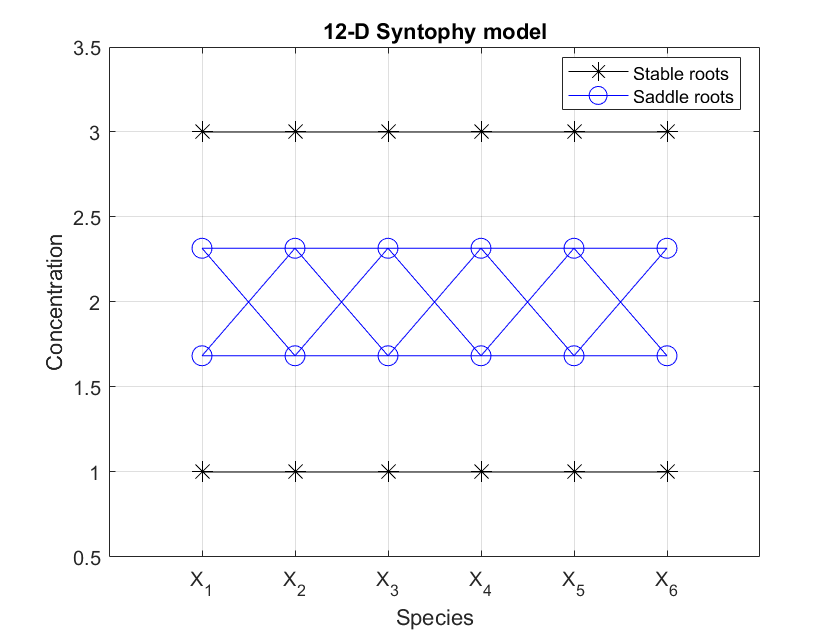

Extract_Hamiltonian

save('..\Data\'+model_name+'_Ham.mat')

load _Ham.mat from 'data' folder

$$pos\_root\_arr = \left(\begin{array}{ccc} 15.2195 & 2.1677 & 12.3127\\ 1.5159 & 0.2159 & 0.0435\\ 3.5437 & 0.5047 & 0.2474 \end{array}\right)$$

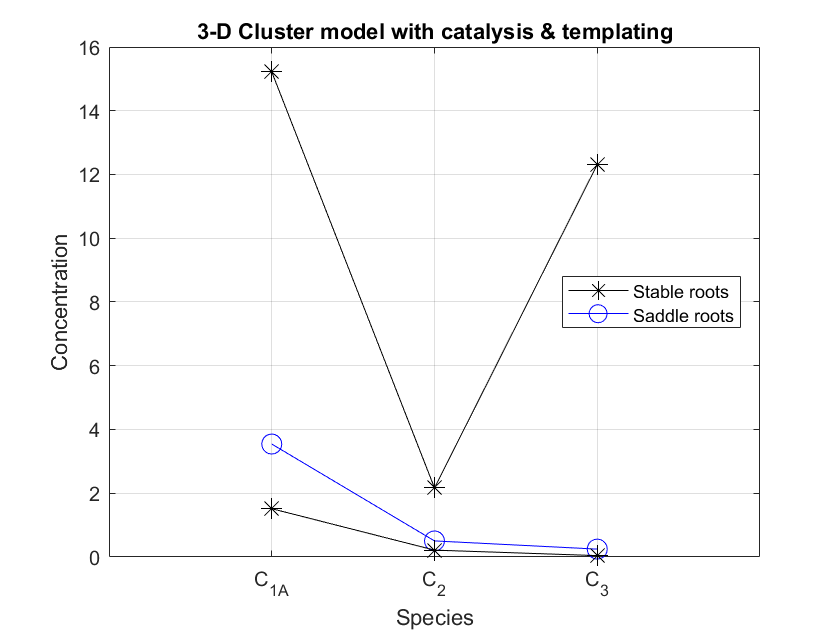

load('..\Data\'+model_name+'_Ham.mat')

## Get input for Bertini

Bertini is a polynomial root solver which takes input in a specific format and outputs all the roots of the system of polynomials.

$$pos\_root\_arr = \left(\begin{array}{cc} 68 & 8\\ 80 & 2\\ 48 & 18 \end{array}\right)$$

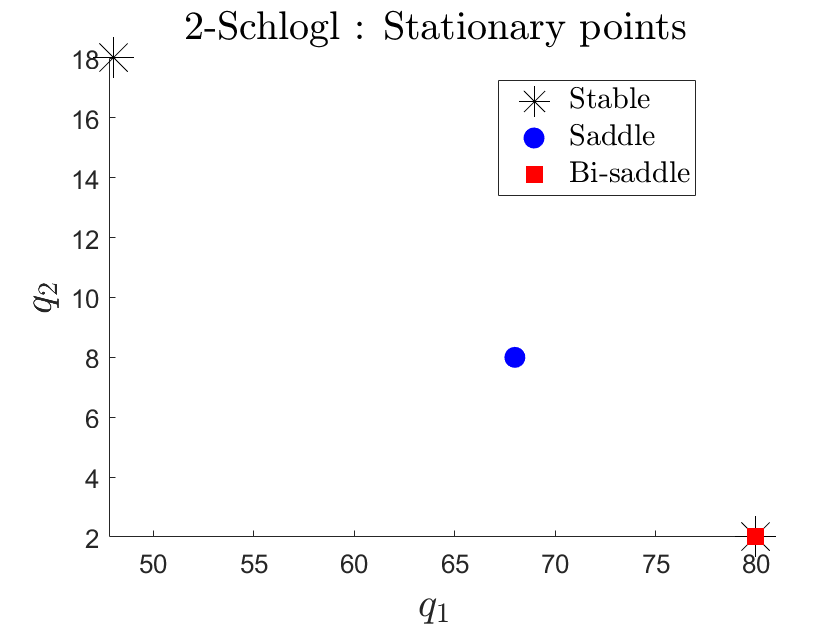

filnam = '..\Data\Bertini\'+model_name + "_bert.txt";

Bertini_file_input
fclose('all')

Now open cygwin and use

Go to cygrdive/username/folder with Bertini

>>cd  .../Data/Bertini

>>./Bertini filnam

Then rename real_finite_solutions file as filnam_roots.txt and paste in the Data folder.

ans = "Computing time"

Elapsed time is 0.072666 seconds.


ans = "Simulation time"

ans =   52.234999999999999


ans = "Computing time"

Elapsed time is 0.043718 seconds.


ans = "Simulation time"

ans =   47.480000000000004


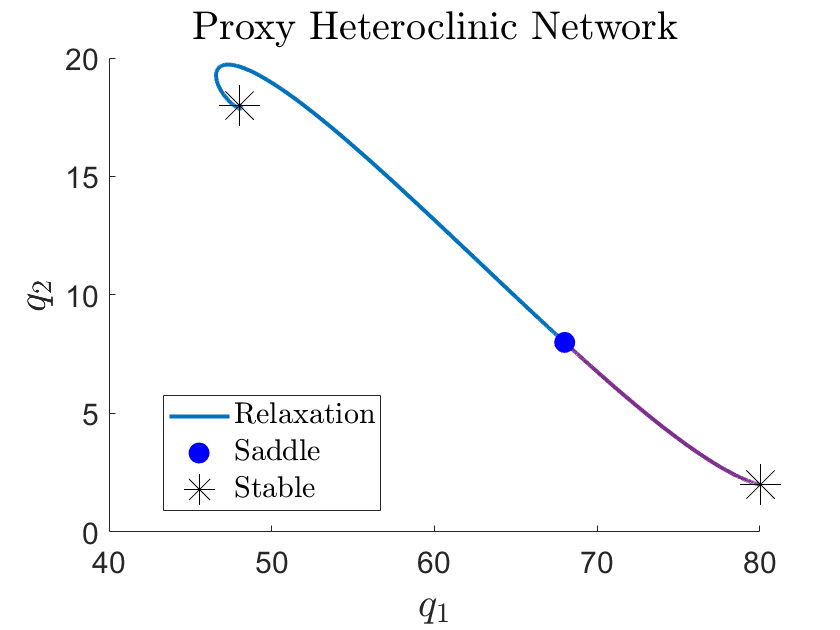

hc_net =      1     3     2


$$pos\_root\_arr = \left(\begin{array}{cc} 68 & 8\\ 80 & 2\\ 48 & 18 \end{array}\right)$$

filnam

## Get roots

#### Bertini

filnam_sol = '..\Data\'+model_name+ "_bert_roots.txt"
Read_bert_root

Plots are saved in '4 Plot and publish' folder.

#### 3+ dim MATLAB roots

get_roots

#### 2 dim MATLAB roots

get_roots_2D

## Heteroclinic Network

Data saved in

'..\Data\' + model_name + '_hq qcnet.mat'

Heteroclinic_network

## Updates needed

- Write a shell script to do get bertini root file. Or integrate matlab bertini with this code. 